format long eng;
kbr1b_x = importdata("KBR1B_2020-09-17_Y_04.txt");
gni1b_a = importdata("GNI1B_2020-09-17_C_04.txt");
gni1b_b = importdata("GNI1B_2020-09-17_D_04.txt");
sca1b_a = importdata("SCA1B_2020-09-17_C_04.txt");
sca1b_b = importdata("SCA1B_2020-09-17_D_04.txt");

los = gni1b_b.data(:, 1: 3) - gni1b_a.data(:, 1: 3);
dis = sqrt(sum(los.^2, 2));
los = los ./ dis;
rotm_a = zeros(17280, 3, 3);
rotm_b = zeros(17280, 3, 3);
eqa = zeros(17280, 6);
eqb = kbr1b_x(:, 2) - dis(1: 5: end);
for i = 1: 17280
    eqa(i, 1: 3) = los(i*5-4, :) * quat2rotm(sca1b_a.data(i*5-4, 2: 5));
    eqa(i, 4: 6) = los(i*5-4, :) * quat2rotm(sca1b_b.data(i*5-4, 2: 5));
end
eqa(:, 1: 3) = -eqa(:, 1: 3);
diff_eqa = diff(eqa, 1);
% 10522: 11121
% 10822: 11421
% 10822: 11421
% 8636: 9235

% 8636: 9235

diff2_eqa = diff(diff_eqa, 1);
diff3_eqa = diff(diff2_eqa, 1);
diff_eqb = diff(kbr1b_x(:, 2) - dis(1: 5: end));
diff2_eqb = diff(kbr1b_x(:, 2) - dis(1: 5: end), 2);
diff3_eqb = diff(diff2_eqb);
diff2_eqb = filter_pdfree(Num, diff2_eqb);
diff2_eqa = filter_pdfree(Num, diff2_eqa);
diff3_eqa = filter_pdfree(Num, diff3_eqa);
diff3_eqb = filter_pdfree(Num, diff3_eqb);
% fft_diff3_eqb = fft(diff3_eqb(10522: 11021));
% fft_diff3_eqa = [fft(diff3_eqa(10522: 11021, 4)), fft(diff3_eqa(10522: 11021, 5))];
% eqb = [fft_diff3_eqb(11); fft_diff3_eqb(21)];
% eqa = [fft_diff3_eqa(11, :); fft_diff3_eqa(21, :)];
% eqa_real = real(eqa);
% eqa_imag = imag(eqa);
% eqb_real = real(eqb);
% eqb_imag = imag(eqb);
% 
% eqa_abs = abs(eqa);
% eqa_ang = angle(eqa);
% eqb_abs = abs(eqb);
% eqb_ang = angle(eqb);

lsqr(diff3_eqa(4036: 4036+600, [2 3 5 6]), diff3_eqb(4036: 4036+600) - diff3_eqa(4036: 4036+600, [1 4]) * [1.444; 1.444])

lsqr 在 迭代 4 停止，而没有收敛到所需容差 1e-06，
这是因为已达到最大迭代数。
迭代返回的 (数目 4) 的相对残差为 0.98。


ans =    -90.0558257362401e-006
    486.125914432574e-006
   -7.22759291213943e-003
    16.2887780730987e-003


lsqr(diff2_eqa(4036: 4036+600, [2 3 4 5 6]), diff2_eqb(4036: 4036+600) - 1.444 * diff2_eqa(4036: 4036+600, 1))

lsqr 在解的 迭代 5 处收敛，并且相对残差为 0.98。


ans =     245.122948588327e-006
    646.146994733951e-006
   -11.6332748880261e-006
   -14.6810421793426e-003
    69.3616263033407e-003


lsqr(diff3_eqa(6354: 6354+600, [2 3 4 5 6]), diff3_eqb(6354: 6354+600) - 1.444 * diff3_eqa(6354: 6354+600, 1))

lsqr 在解的 迭代 5 处收敛，并且相对残差为 0.99。


ans =    -6.20629475030042e-003
   -216.398157492183e-006
   -2.76082003808549e-006
    14.0458270563531e-003
   -8.94172170459704e-003


lsqr(diff2_eqa(6354: 6354+600, [2 3 5 6]), diff2_eqb(6354: 6354+600) - diff2_eqa(6354: 6354+600, [1 4]) * [1.444; 1.444])

lsqr 在 迭代 4 停止，而没有收敛到所需容差 1e-06，
这是因为已达到最大迭代数。
迭代返回的 (数目 4) 的相对残差为 0.98。


ans =     52.6407587707645e-003
   -235.890795386939e-006
   -1.71696912361505e-003
   -29.2180313894267e-003


lsqr(diff3_eqa(8624: 8624+600, [2 3 4 5 6]), diff3_eqb(8624: 8624+600) - 1.444 * diff3_eqa(8624: 8624+600, 1))

lsqr 在解的 迭代 5 处收敛，并且相对残差为 0.97。


ans =    -783.678601304884e-006
   -2.35567677942187e-003
   -33.7683090802271e-006
    25.8883833819906e-003
    8.29416732597212e-003


lsqr(diff2_eqa(8624: 8624+600, [2 3 4 5 6]), diff2_eqb(8624: 8624+600) - 1.444 * diff2_eqa(8624: 8624+600, 1))

lsqr 在解的 迭代 5 处收敛，并且相对残差为 0.98。


ans =    -783.198602237070e-006
   -13.1411594606005e-003
   -33.8414745969711e-006
   -31.7139062225077e-003
    18.4488067598521e-003


lsqr(diff3_eqa(10822: 10822+600, [2 3 5 6]), diff3_eqb(10822: 10822+600) - diff3_eqa(10822: 10822+600, [1 4]) * [1.444; 1.444])

lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.99。


ans =    -231.573836146280e-006
    7.92541328993929e-003
   -18.2747401593804e-003
   -35.3069090549136e-003


lsqr(diff2_eqa(10822: 10822+600, [2 3 5 6]), diff2_eqb(10822: 10822+600) - diff2_eqa(10822: 10822+600, [1 4]) * [1.444; 1.444])

lsqr 在 迭代 4 停止，而没有收敛到所需容差 1e-06，
这是因为已达到最大迭代数。
迭代返回的 (数目 4) 的相对残差为 0.99。


ans =    -241.030766192609e-006
    2.61006430520726e-003
    13.7273843962798e-003
   -27.2525450135038e-003


solver_spectral(diff2_eqa(10822: 11421, :), diff2_eqb(10822: 11421), [1 2], 0.2)

lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.21。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.21。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.21。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.22。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.22。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.22。


ans =     382.845300536901e-009   -11.1068699848687e-006
    202.313775978712e-009    473.678952255847e-009


lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.21。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.21。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.21。


ans =     550.611473937551e-009
    284.133426337141e-009


lsqr 在解的 迭代 2 处收敛，并且相对残差为 1.3e-09。


ans =     199.618798163218e-006


solver_spectral(diff3_eqa(10822: 11421, :), diff3_eqb(10822: 11421), [1 2], 0.2)

lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.31。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.31。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.31。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.4。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.4。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.4。


ans =     47.7883041626367e-009   -1.38219522618055e-006
    51.2242826895344e-009    106.997215062733e-009


lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.32。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.32。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.32。


ans =     68.6815142700124e-009
    72.0433517268413e-009


lsqr 在解的 迭代 2 处收敛，并且相对残差为 8.9e-12。


ans =     234.986299100884e-006


solver_spectral(diff2_eqa(4036: 4036+600, :), diff2_eqb(4036: 4036+600), [1 3], 0.2)

lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.13。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.13。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.13。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.09。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.09。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.09。


ans =     395.716871282574e-009   -11.2125140138345e-006
    191.592983768308e-009    184.290007229382e-009


lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.14。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.14。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.14。


ans =     578.817658697633e-009
    268.940208408937e-009


lsqr 在解的 迭代 2 处收敛，并且相对残差为 2.6e-09。


ans =    -660.199537451005e-006


solver_spectral(diff3_eqa(4036: 4036+600, :), diff3_eqb(4036: 4036+600), [1 3], 0.2)

lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.23。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.23。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.23。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.2。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.2。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.2。


ans =     50.3445849153943e-009   -1.41874799891851e-006
    49.2072355095419e-009    54.6174053320549e-009


lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.23。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.23。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.23。


ans =     73.5676551674991e-009
    68.9305830844463e-009


lsqr 在解的 迭代 2 处收敛，并且相对残差为 1.4e-11。


ans =    -613.269270041620e-006


solver_spectral(diff2_eqa(10822: 10822+600, :), diff2_eqb(10822: 10822+600), [1 3], 0.2)

lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.21。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.21。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.21。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.96。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.96。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.96。


ans =     382.911609925767e-009   -21.6965991193584e-009
    202.266865753571e-009    30.4173178175867e-009


lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.21。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.21。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.21。


ans =     550.721112942353e-009
    284.058017190461e-009


lsqr 在解的 迭代 2 处收敛，并且相对残差为 4.6e-12。


ans =     101.548255481564e-003


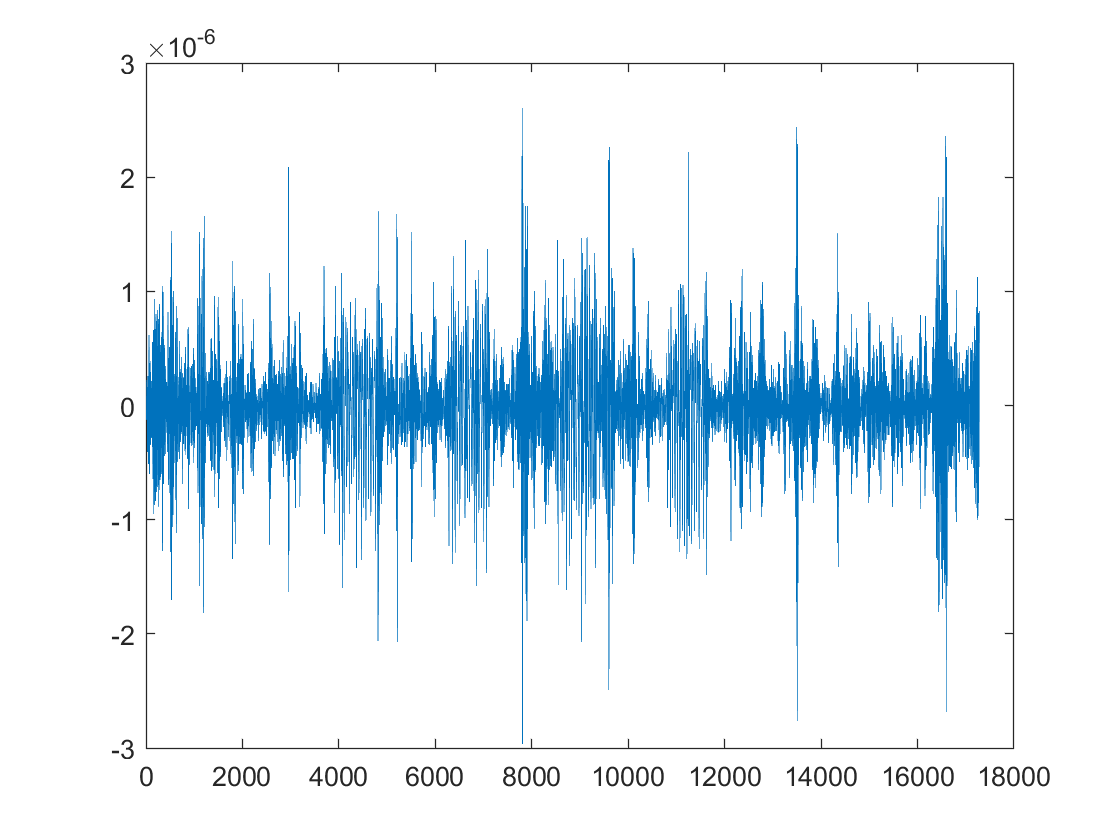

acc_grav = importdata("..//..//temp//acc_grav_calibra2.txt");
acc_grav = acc_grav(1: 86400, :);
%vel_grac = cumtrapz(acc_grav, 1);
acc_grav_rela = [acc_grav(:, 1) - acc_grav(:, 4), acc_grav(:, 2) - acc_grav(:, 5), acc_grav(:, 3) - acc_grav(:, 6)];
%vel_grav_rela = [vel_grav(:, 1) - vel_grav(:, 4), vel_grav(:, 2) - vel_grav(:, 5), vel_grav(:, 3) - vel_grav(:, 6)];
gnv_a = importdata("GNV1B_2020-09-17_C_04.txt");
gnv_b = importdata("GNV1B_2020-09-17_D_04.txt");
gni_a = importdata("GNI1B_2020-09-17_C_04.txt");
gni_b = importdata("GNI1B_2020-09-17_D_04.txt");
kbr_x = importdata("KBR1B_2020-09-17_Y_04.txt");

range_acc = kbr_x(:, 4);

pos_rela = gnv_a.data(:, 1: 3) - gnv_b.data(:, 1: 3);
pos_rela_i = gni_a.data(:, 1: 3) - gni_b.data(:, 1: 3);
los = pos_rela ./ sqrt(sum(pos_rela.^2, 2));
los_i = pos_rela_i ./ sqrt(sum(pos_rela_i.^2, 2));
vel_rela = gni_a.data(:, 7: 9) - gni_b.data(:, 7: 9);
los_vec = vel_rela ./ sqrt(sum(pos_rela.^2, 2)) - pos_rela_i .* dot(los_i, vel_rela, 2) ./ sum(pos_rela.^2, 2);

range_acc_grav = zeros(length(los), 1);
for i = 1: length(range_acc_grav)
    range_acc_grav(i) = dot(acc_grav_rela(i, :), los(i, :)) + dot(vel_rela(i, :), los_vec(i, :));
end
range_acc_grav = range_acc_grav(1: 5: length(range_acc_grav));
range_acc_res = range_acc - range_acc_grav;
figure; plot(range_acc_res)

a1 = spectral_component(filter_pdfree(Num, range_acc_res(4036: 4036+600)), 0.2)

lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.54。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.54。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.54。


a1 =     582.590644657358e-009
    210.533130371327e-009


a2 = spectral_component(filter_pdfree(second_order_diff(60, 30), eqa(4036: 4036+600, 1)) / 25, 0.2)

lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.17。
lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.17。
lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.17。


a2 =     401.331417029793e-009
    197.045355481219e-009


a3 = spectral_component(filter_pdfree(second_order_diff(60, 30), eqa(4036: 4036+600, 3)) / 25, 0.2)

lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.16。
lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.16。
lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.16。


a3 =     11.3052460521119e-006
    138.364849245198e-009


q1 = -(a1(1) - 1.4443985 * a2(1)) / a3(1)

q1 =    -257.238797213761e-006


a1 = spectral_component(filter_pdfree(Num, range_acc_res(6354: 6354+600)), 0.2)

lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.65。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.65。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.65。


a1 =     553.933448167439e-009
    217.247626094234e-009


a2 = spectral_component(filter_pdfree(second_order_diff(60, 30), eqa(6354: 6354+600, 1)) / 25, 0.2)

lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.14。
lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.14。
lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.14。


a2 =     387.726023715323e-009
    200.283338748988e-009


a3 = spectral_component(filter_pdfree(second_order_diff(60, 30), eqa(6354: 6354+600, 3)) / 25, 0.2)

lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.14。
lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.14。
lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.14。


a3 =     11.2356508738181e-006
    18.4300077450259e-009


q2 = (a1(1) - 1.4443985 * a2(1)) / a3(1)

q2 =    -542.686753657105e-006


q5 = (a1(1) - 1.4443985 * a2(1) + 17*0.8e-6*(2*pi/250.0)^2) / a3(1)

q5 =     221.888771800548e-006


a1 = spectral_component(filter_pdfree(Num, range_acc_res(8624: 8624+600)), 0.2)

lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.71。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.71。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.71。


a1 =     587.719391490414e-009
    301.943118866271e-009


a2 = spectral_component(filter_pdfree(second_order_diff(60, 30), eqa(8624: 8624+600, 1)) / 25, 0.2)

lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.12。
lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.12。
lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.12。


a2 =     400.710708303069e-009
    205.510460830848e-009


a3 = spectral_component(filter_pdfree(second_order_diff(60, 30), eqa(8624: 8624+600, 2)) / 25, 0.2)

lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.13。
lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.13。
lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.13。


a3 =     11.4015587783858e-006
    16.6064572742728e-009


q3 = -(a1(1) - 1.4443985 * a2(1)) / a3(1)

q3 =    -783.528433012057e-006


a1 = spectral_component(filter_pdfree(Num, range_acc_res(10822: 10822+600)), 0.2)

lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.69。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.69。
lsqr 在解的 迭代 2 处收敛，并且相对残差为 0.69。


a1 =     564.418881391334e-009
    225.922196053970e-009


a2 = spectral_component(filter_pdfree(second_order_diff(60, 30), eqa(10822: 10822+600, 1)) / 25, 0.2)

lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.24。
lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.24。
lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.24。


a2 =     384.754277818673e-009
    202.057174489329e-009


a3 = spectral_component(filter_pdfree(second_order_diff(60, 30), eqa(10822: 10822+600, 2)) / 25, 0.2)

lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.25。
lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.25。
lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.25。


a3 =     11.1841460318733e-006
    399.392264583243e-009


q4 = (a1(1) - 1.4443985 * a2(1)) / a3(1)

q4 =     776.132537676262e-006


(q4 + q3) / 2.0

ans =    -3.69794766789727e-006


q6 = (a1(1) - 1.4443985 * a2(1) - 17*0.8e-6*(2*pi/250.0)^2) / a3(1)

q6 =     8.03601548973226e-006
